% AAE 546 HW 12 Problem 5
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
addpath(genpath("C:\Users\Tomo\Desktop\studies\2020-Fall\AAE564\matlab_simulink"))

% System requirements 
zeta = 0.7071;
ts = 5;
wn = 4.6 / zeta / ts;
p1 = -zeta*wn+wn^2*sqrt(1-zeta^2)*1j;
p2 = -zeta*wn-wn^2*sqrt(1-zeta^2)*1j;
% p1 = -2 + 0.8j;
% p2 = -2 - 0.8j;
p3 = -1;
p4 = -1.22;
p5 = -0.029;
p6 = -0.31;
pp = 0.1*rand(1,4);
%p = [p1, p2, p3, p4, p5, p6];
p = [p1, p2, pp];

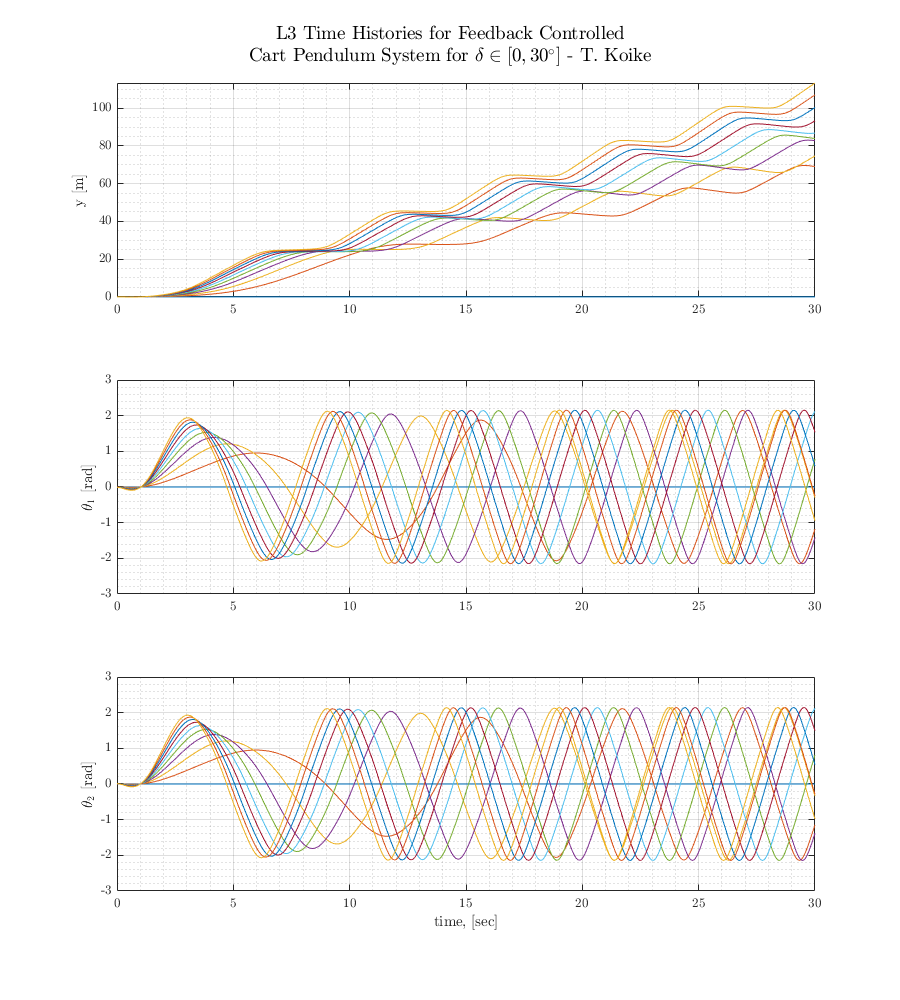

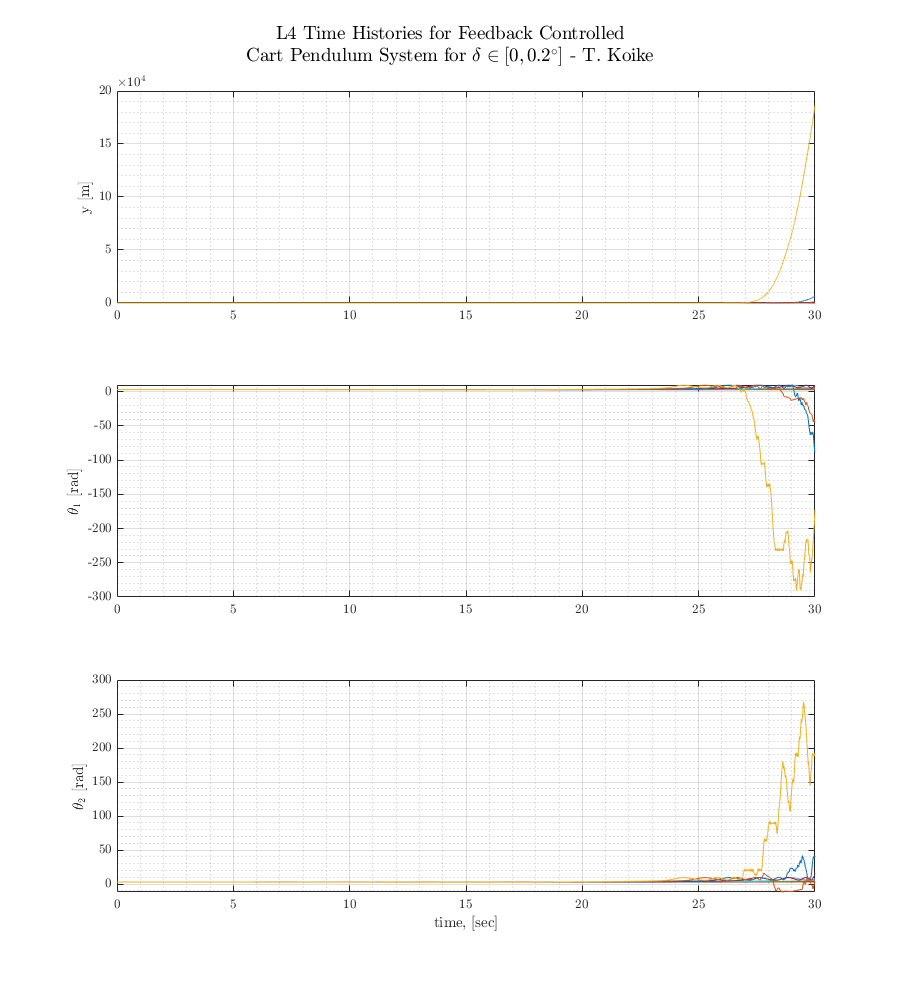

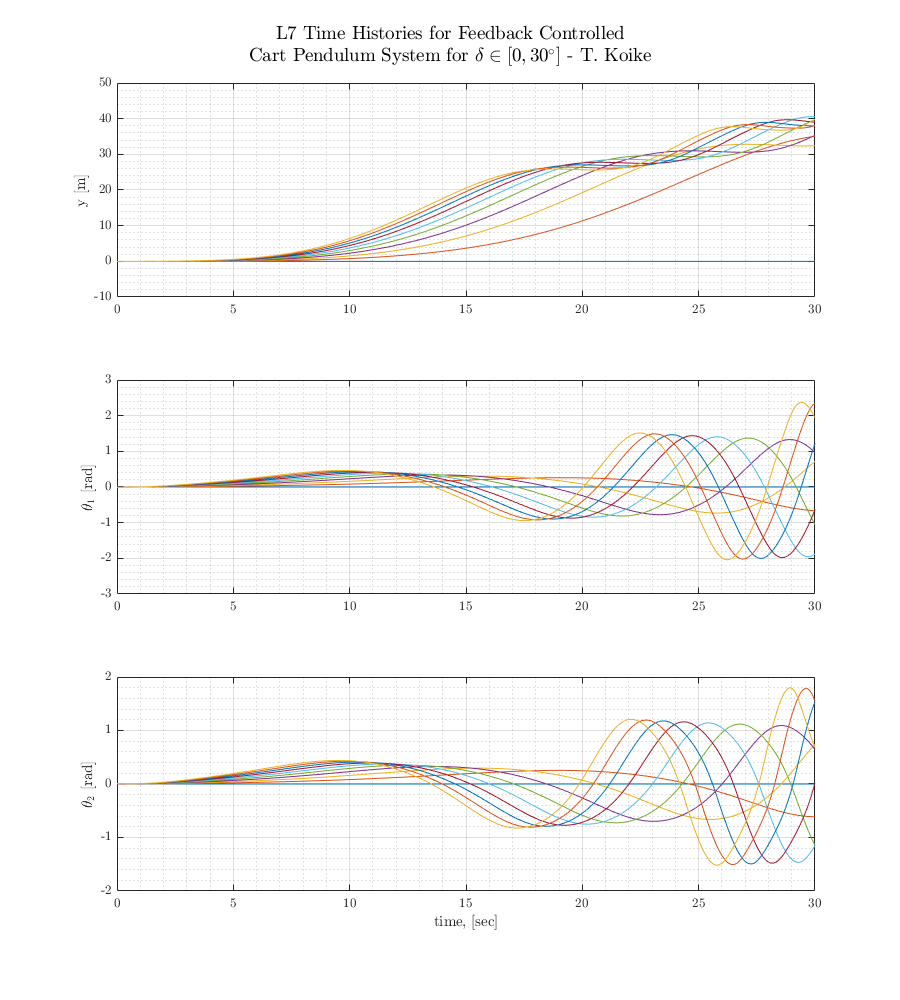

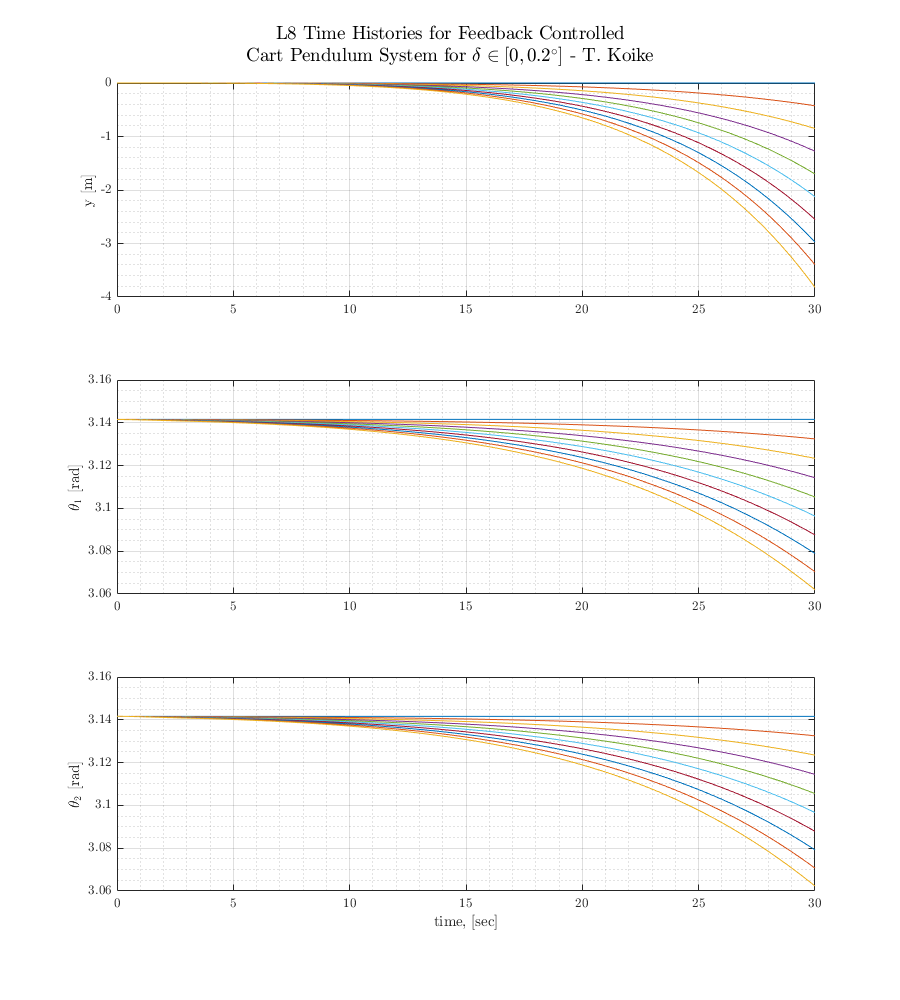

global m l g ye theta1e theta2e
warning('off');
param_combo = ["L3","L4","L7","L8"]; %["L3","L4","L7","L8"]
for i = 1:numel(param_combo)
    define_params(param_combo(i));
    xe = trim('db_pend_cart_lin');
    [A, B, C, D] = linmod('db_pend_cart_lin',xe);
    lin_sys(i).Amat = A;
    lin_sys(i).Bmat = B;
    lin_sys(i).Cmat = C;
    lin_sys(i).Dmat = D;
    
    % Compute the gain
    K    = -place(A, B, p);
    lin_sys(i).K = K;
    
    % Plotting 
    % Initialize figure
    fig = figure('Renderer',"painters", 'Position', [10 10 900 1000]); 
    delta_max = ["30","0.2","30","0.2"];
    for delta = linspace(0,deg2rad(str2double(delta_max(i))),10)
        % Initial conditions 
        dyi = 0; 
        u = 0; 
        yi = ye + dyi; 
        theta1i = theta1e - deg2rad(delta); 
        theta2i = theta2e + deg2rad(delta);
        IC_ss = [yi, theta1i, theta2i, 0, 0, 0];
        
        % Simulate 
        simout = sim('db_pend_cart_lin_inputFeedback');
        lin_sys(i).simout = simout;   
        
        % Plot 
        time = simout.tout;
        data = simout.res.signals.values;
        y = data(:,1);
        theta1 = data(:,2);
        theta2 = data(:,3);
        
        
        subplot(3,1,1) 
        grid on; grid minor; box on;
        plot(time,y)
        hold on; grid on; grid minor; box on;
        ylabel('y [m]')
        subplot(3,1,2)
        grid on; grid minor; box on;
        plot(time,theta1)
        hold on; grid on; grid minor; box on; 
        ylabel('$\theta_1$ [rad]')
        subplot(3,1,3)
        grid on; grid minor; box on;
        plot(time,theta2)
        hold on; grid on; grid minor; box on;
        ylabel('$\theta_2$ [rad]')
    end
    hold off;
    xlabel('time, [sec]')
    line1 = param_combo(i)+' Time Histories for Feedback Controlled';
    line2 = 'Cart Pendulum System for $\delta\in[0,'+delta_max(i)+'^{\circ}]$ - T. Koike';
    title_string = {line1,line2};
    sgtitle(title_string)
    %saveas(fig, 'p5_'+param_combo(i)+'.png');
end

% for i = 1:numel(param_combo) 
%     % Plot
%     simout = lin_sys(i).simout;
%     time = simout.tout;
%     data = simout.res.signals.values;
%     y = data(:,1);
%     theta1 = data(:,2);
%     theta2 = data(:,3);
%     
%     % Plotting 
%     fig = figure('Renderer',"painters", 'Position', [10 10 900 1000]);
%     subplot(3,1,1)
%     plot(time,y)
%     grid on; grid minor; box on;
%     ylabel('y [m]')
%     subplot(3,1,2)
%     plot(time,theta1)
%     grid on; grid minor; box on;
%     ylabel('$\theta_1$ [rad]')
%     subplot(3,1,3)
%     plot(time,theta2)
%     grid on; grid minor; box on;
%     ylabel('$\theta_2$ [rad]')
%     xlabel('time, [sec]')
%     title_string = {param_combo(i)+' Time Histories for Feedback Controlled',['' ...
%         'Cart Pendulum System - T. Koike']};
%     sgtitle(title_string)
%     saveas(fig, 'p5_'+param_combo(i)+'.png');
% end

% reshape(p, 2, 3)

% A=lin_sys(4).Amat
% B=lin_sys(4).Bmat
% C=lin_sys(4).Cmat
% D=lin_sys(4).Dmat
% K=lin_sys(4).K

function define_params(L)
    % Function to define parameters
    global m l g ye theta1e theta2e
    if L == "L1"
        m = [2,1,1]; l = [1,1]; g = 1; % P1
        ye = 0; theta1e = 0; theta2e = 0; % E1
    elseif L == "L2"
        m = [2,1,1]; l = [1,1]; g = 1; % P1
        ye = 0; theta1e = pi; theta2e = pi; % E2 
    elseif L == "L3"
        m = [2,1,1]; l = [1,0.99]; g = 1; % P2
        ye = 0; theta1e = 0; theta2e = 0; % E1
    elseif L == "L4"
        m = [2,1,1]; l = [1,0.99]; g = 1; % P2
        ye = 0; theta1e = pi; theta2e = pi; % E2 
    elseif L == "L5"
        m = [2,1,0.5]; l = [1,1]; g = 1; % P3
        ye = 0; theta1e = 0; theta2e = 0; % E1
    elseif L == "L6"
        m = [2,1,0.5]; l = [1,1]; g = 1; % P3
        ye = 0; theta1e = pi; theta2e = pi; % E2 
    elseif L == "L7"
        m = [2,1,1]; l = [1,0.5]; g = 1; % P4
        ye = 0; theta1e = 0; theta2e = 0; % E1
    elseif L == "L8"
        m = [2,1,1]; l = [1,0.5]; g = 1; % P4
        ye = 0; theta1e = pi; theta2e = pi; % E2
    else
        print('error: did not match any')
    end
end